disp('EX1')

EX1


syms q1 q2 q3 l1 Xx Xy Xz Yx Yy Yz Zx Zy Zz Px Py Pz

R01=TransfoMat('r','z',q1)

$$R01 = \left(\begin{array}{cccc} \cos\left(q_{1}\right) & -\sin\left(q_{1}\right) & 0 & 0\\ \sin\left(q_{1}\right) & \cos\left(q_{1}\right) & 0 & 0\\ 0 & 0 & 1 & 0\\ 0 & 0 & 0 & 1 \end{array}\right)$$

R12=TransfoMat('t','z',l1)

$$R12 = \left(\begin{array}{cccc} 1 & 0 & 0 & 0\\ 0 & 1 & 0 & 0\\ 0 & 0 & 1 & l_{1}\\ 0 & 0 & 0 & 1 \end{array}\right)$$

R23=TransfoMat('r','x',q2)

$$R23 = \left(\begin{array}{cccc} 1 & 0 & 0 & 0\\ 0 & \cos\left(q_{2}\right) & -\sin\left(q_{2}\right) & 0\\ 0 & \sin\left(q_{2}\right) & \cos\left(q_{2}\right) & 0\\ 0 & 0 & 0 & 1 \end{array}\right)$$

R34=TransfoMat('t','y',q3)

$$R34 = \left(\begin{array}{cccc} 1 & 0 & 0 & 0\\ 0 & 1 & 0 & q_{3}\\ 0 & 0 & 1 & 0\\ 0 & 0 & 0 & 1 \end{array}\right)$$


R14=R01*R12*R23*R34

$$R14 = \left(\begin{array}{cccc} \cos\left(q_{1}\right) & -\cos\left(q_{2}\right)\,\sin\left(q_{1}\right) & \sin\left(q_{1}\right)\,\sin\left(q_{2}\right) & -q_{3}\,\cos\left(q_{2}\right)\,\sin\left(q_{1}\right)\\ \sin\left(q_{1}\right) & \cos\left(q_{1}\right)\,\cos\left(q_{2}\right) & -\cos\left(q_{1}\right)\,\sin\left(q_{2}\right) & q_{3}\,\cos\left(q_{1}\right)\,\cos\left(q_{2}\right)\\ 0 & \sin\left(q_{2}\right) & \cos\left(q_{2}\right) & l_{1}+q_{3}\,\sin\left(q_{2}\right)\\ 0 & 0 & 0 & 1 \end{array}\right)$$


DGM=eval(R14)

$$DGM = \left(\begin{array}{cccc} \cos\left(q_{1}\right) & -\cos\left(q_{2}\right)\,\sin\left(q_{1}\right) & \sin\left(q_{1}\right)\,\sin\left(q_{2}\right) & -q_{3}\,\cos\left(q_{2}\right)\,\sin\left(q_{1}\right)\\ \sin\left(q_{1}\right) & \cos\left(q_{1}\right)\,\cos\left(q_{2}\right) & -\cos\left(q_{1}\right)\,\sin\left(q_{2}\right) & q_{3}\,\cos\left(q_{1}\right)\,\cos\left(q_{2}\right)\\ 0 & \sin\left(q_{2}\right) & \cos\left(q_{2}\right) & l_{1}+q_{3}\,\sin\left(q_{2}\right)\\ 0 & 0 & 0 & 1 \end{array}\right)$$


P = DGM(1:3,4)

$$P = \left(\begin{array}{c} -q_{3}\,\cos\left(q_{2}\right)\,\sin\left(q_{1}\right)\\ q_{3}\,\cos\left(q_{1}\right)\,\cos\left(q_{2}\right)\\ l_{1}+q_{3}\,\sin\left(q_{2}\right) \end{array}\right)$$


q1=atan(P(2)/P(1))

$$q1 = -\mathrm{atan}\left(\frac{\cos\left(q_{1}\right)}{\sin\left(q_{1}\right)}\right)$$

q2=P(1)/(P(3)-l1)

$$q2 = -\frac{\cos\left(q_{2}\right)\,\sin\left(q_{1}\right)}{\sin\left(q_{2}\right)}$$


q3=(P(3)-l1)/P(1)

$$q3 = -\frac{\sin\left(q_{2}\right)}{\cos\left(q_{2}\right)\,\sin\left(q_{1}\right)}$$

% disp('EX2')
% 
% 
% l1=0.5;
% l3=0.2; l2=l3;
% 
% L1 = Link('theta',0,'a',0,'alpha',pi/2,'modified')
% L2 = Link('d',0,'a',l1,'alpha',q2,'modified')
% L3 = Link('d',l2,'a',0,'alpha',-q3,'modified')
% L4 = Link('d',l3,'a',0,'alpha',pi/2,'modified')
% 
% bot=SerialLink([L1 L2 L3],'name','robocop')
% bot.tool=transl(0.2,0,0)
% bot.fkine([q1 q2 q3])
% 
% T1=trotz(pi/2,'deg');
% T2=transl(l1,0,0)*trotz(q2);
% T3=transl(l2,0,0)*trotz(q3);
% T4=transl(l3,0,0)*trotz(pi/2,'deg');
% 
% q=bot.ikine(T1*T2*T3*T4.*[1 1 1 0 0 0])


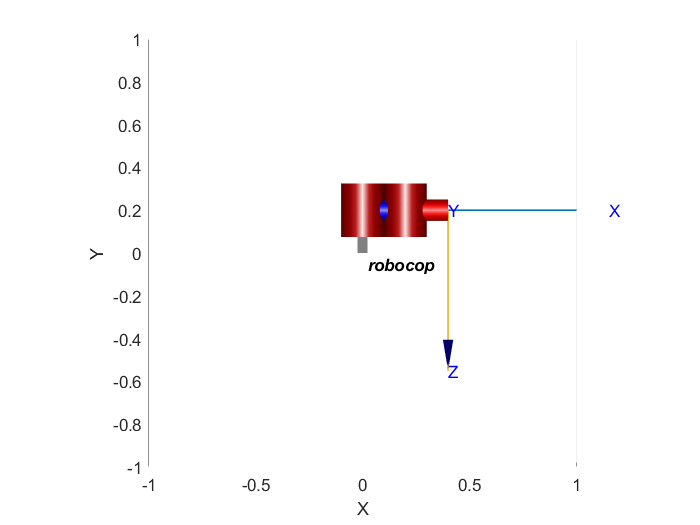


clear; clc; close all;
l1 = 0.5;
l2 = 0.2;
l3 = 0.2;
L1 = Link('a', 0, 'alpha', pi/2, 'theta', pi/2, 'modified');
L2 = Link('d', 0, 'a', l1, 'alpha', 0, 'modified');
L3 = Link('d', 0, 'a', l2, 'alpha', 0, 'modified');


bot = SerialLink( [ L1 L2 L3] , 'name' , 'robocop' );
bot.tool=transl(l3, 0, 0);

T1 = transl(0.1414, -0.3, 0.8414)*troty(-pi/2);
T2 = transl(0.4, 0.2, 0.5)*troty(pi);

T = ctraj(T1, T2, 50);
q0=[0, 0.2, 0.3];
M=[1 1 1 0 0 0];

q=bot.ikine(T, q0, M);

bot.plot(q, 'workspace', [-1, 1, -1, 1, -1, 1]);